### **Set up and create DataSet objects**

clc;
warning("off","all")

% make data object
[obj_arr, mset_arr] = make_objs();

### **Select and plot the chosen dataset; set Y, M**

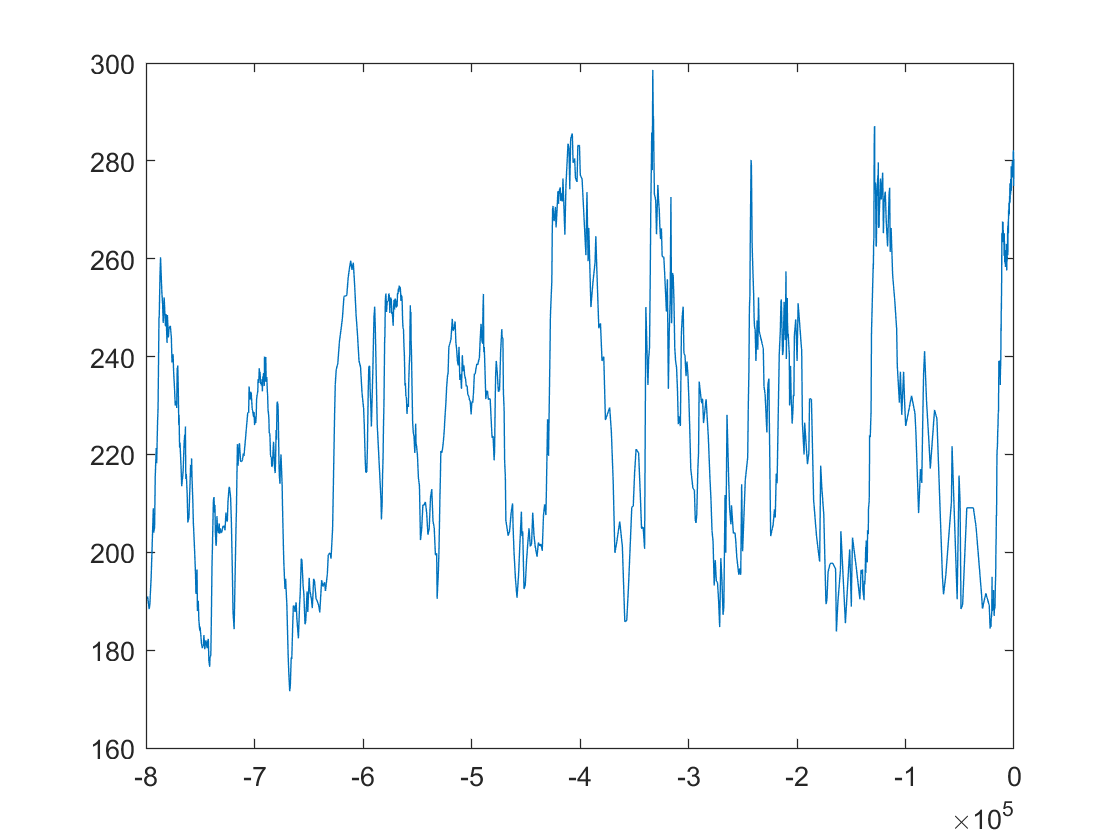

close all;
epica_data = obj_arr{1};    % 1 = CO2, 2 = CH4, 3 = d18O
plot(epica_data.X,epica_data.Y);


% set number of "years" and "months" to divide data into
Y = 20;
M = 50;

### **Run findanf function & plot a(k), N(k), f(tau) over multiple m values + Woosok estimate**

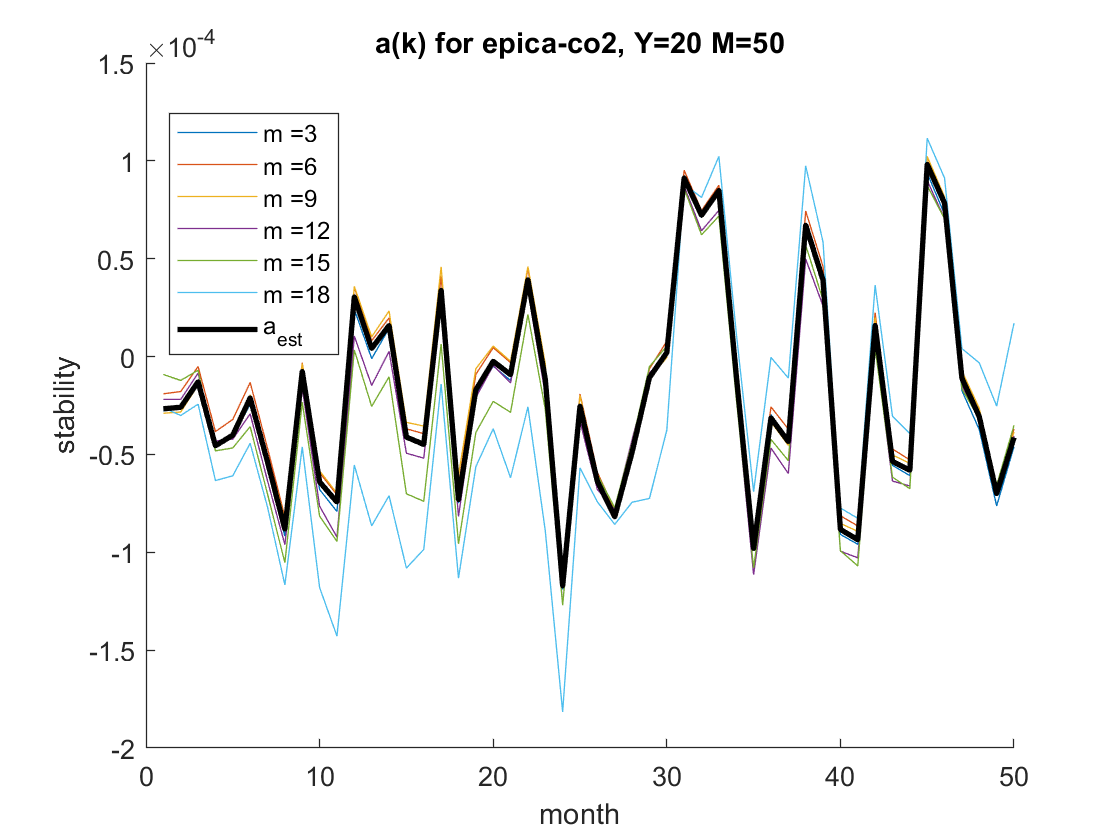

close all;

% run findanf_epica for range of m-values
n = 3;
m_arr = linspace(n,Y-2,(Y-2)/n);
for m=m_arr
    
    [a_final,N,f,~] = findanf_epica(epica_data,Y,M,m);
    
    figure(1);
    hold on;
    plot(a_final);
    
    figure(2);
    hold on;
    plot(N);
    
    figure(3);
    hold on;
    plot(f);
    
end

% run findanf Woosok estimate version
[a_est,N_est] = findanf_est(epica_data,Y,M);

% plot a-values in fig. 1
figure(1);
hold on;
plot(a_est,'LineWidth',2,'Color','black');
legend_cell = strcat('m = ', string(num2cell(m_arr)));
legend_cell{end+1} = 'a_{est}';
legend(legend_cell,'Location','Best');
xlabel("month");
ylabel("stability");
title(sprintf("a(k) for %s, Y=%d M=%d", epica_data.data_name, Y, M));
saveas(gcf,sprintf("%s_a_%d-%d.jpeg",epica_data.data_name,Y,M));

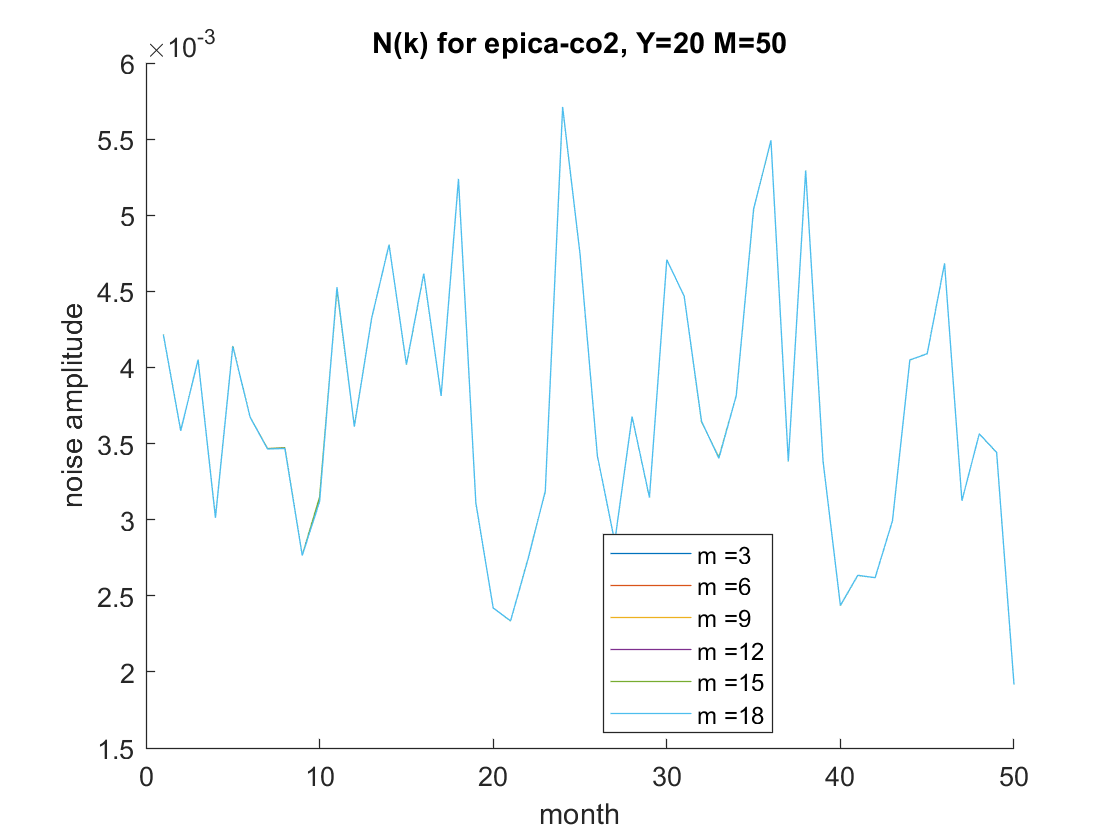


% plot N-values in fig. 2
figure(2);
hold on;
% plot(N_est,'LineWidth',2,'Color','black');
legend_cell = strcat('m = ', string(num2cell(m_arr)));
% legend_cell{end+1} = 'N_{est}';
legend(legend_cell,'Location','Best');
xlabel("month");
ylabel("noise amplitude");
title(sprintf("N(k) for %s, Y=%d M=%d", epica_data.data_name, Y, M));
saveas(gcf,sprintf("%s_N_%d-%d.jpeg",epica_data.data_name,Y,M));

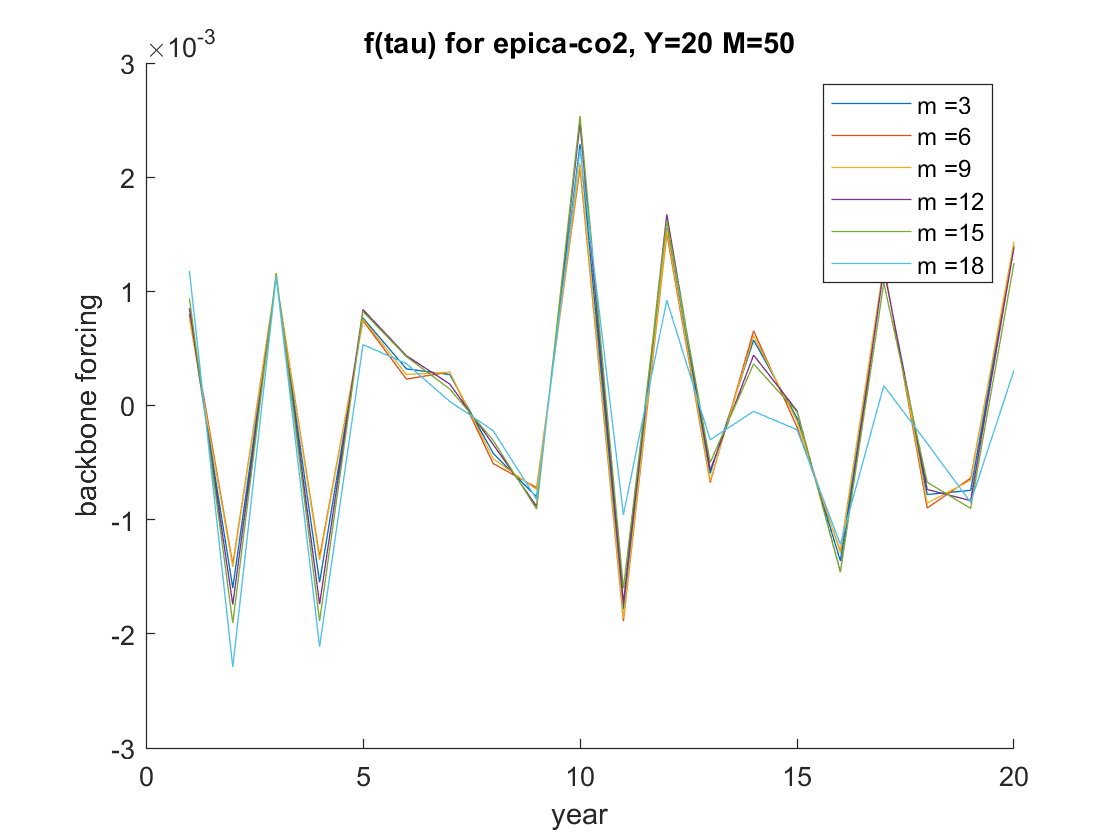


% plot f-values in fig. 3
figure(3);
xlabel("year");
ylabel("backbone forcing");
title(sprintf("f(tau) for %s, Y=%d M=%d",epica_data.data_name,Y,M));
legend_cell = strcat('m = ', string(num2cell(m_arr)));
legend_cell{end+1} = 'a_{est}';
legend(legend_cell);
saveas(gcf,sprintf("%s_f_%d-%d.jpeg",epica_data.data_name,Y,M));

### **Estimate response timescale & year offset for B(m)**

[a_est,N_est] = findanf_est(epica_data,Y,M);

M_length = range(epica_data.X) / (Y*M)

M_length = 798.3750

int_aest = sum(a_est) / M_length;
T_aest = 1 / abs(int_aest);
num_M_est = T_aest / M_length;
num_Y_est = num_M_est / M

num_Y_est = 20.7614

Y_est_round = round(num_Y_est);

% 34 yrs -
% CO2: 25.25
% CH4: 6.17
% temp: 11.80

% 20 yrs -
% CO2: 20.76
% CH4: 6.12
% temp: 11.08

### **plot power spectra**

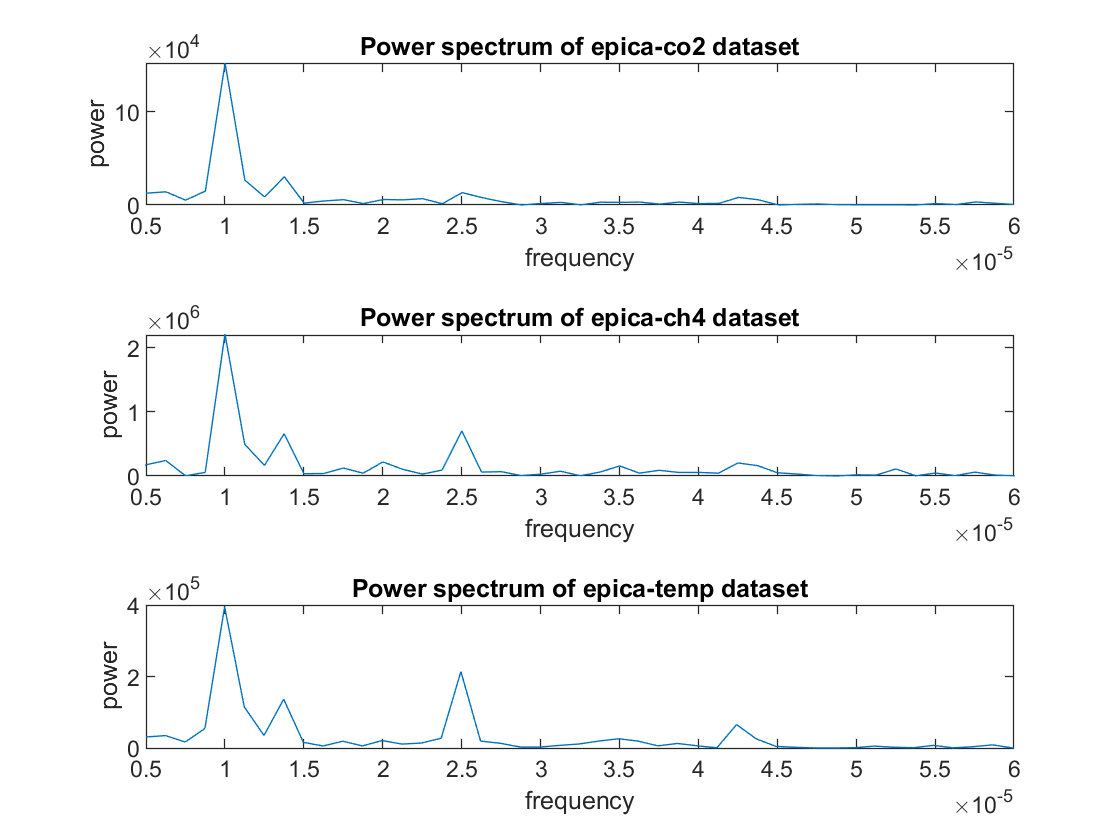

close all;

tiledlayout(3,1);

power_spectrum(obj_arr{1});
power_spectrum(obj_arr{2});
power_spectrum(obj_arr{3});

### plot of a sample S, A, B

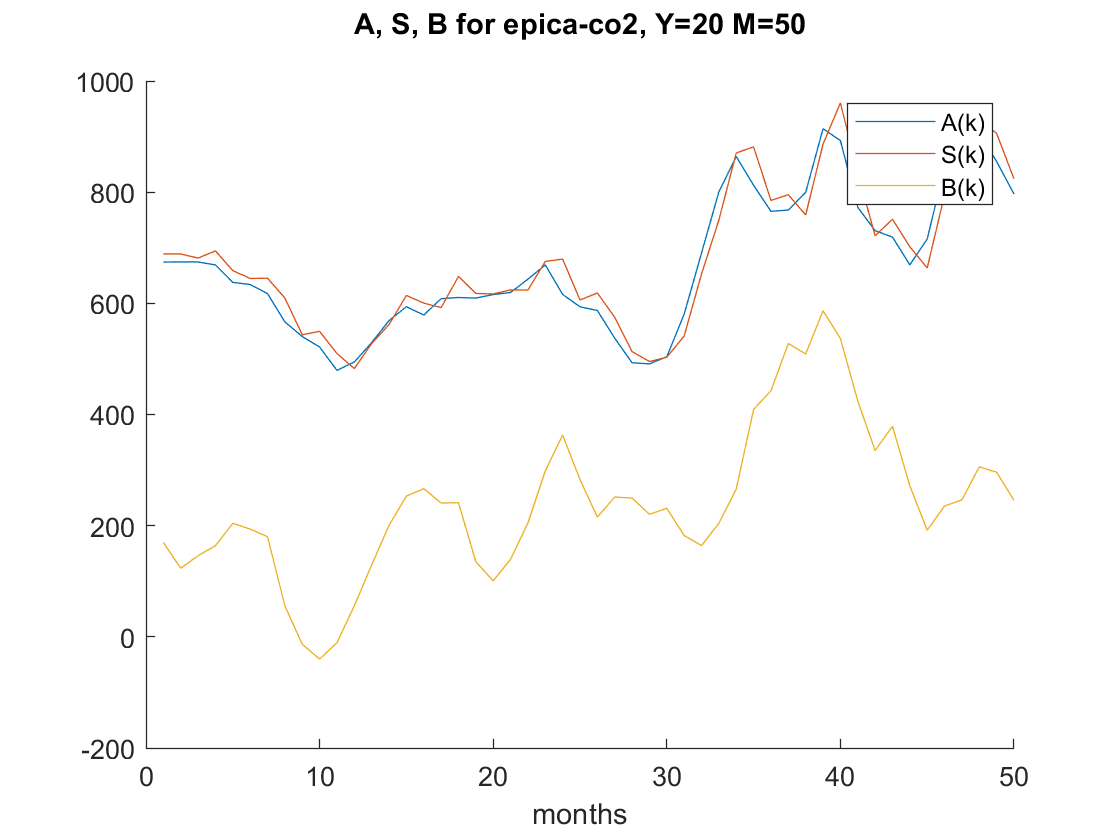

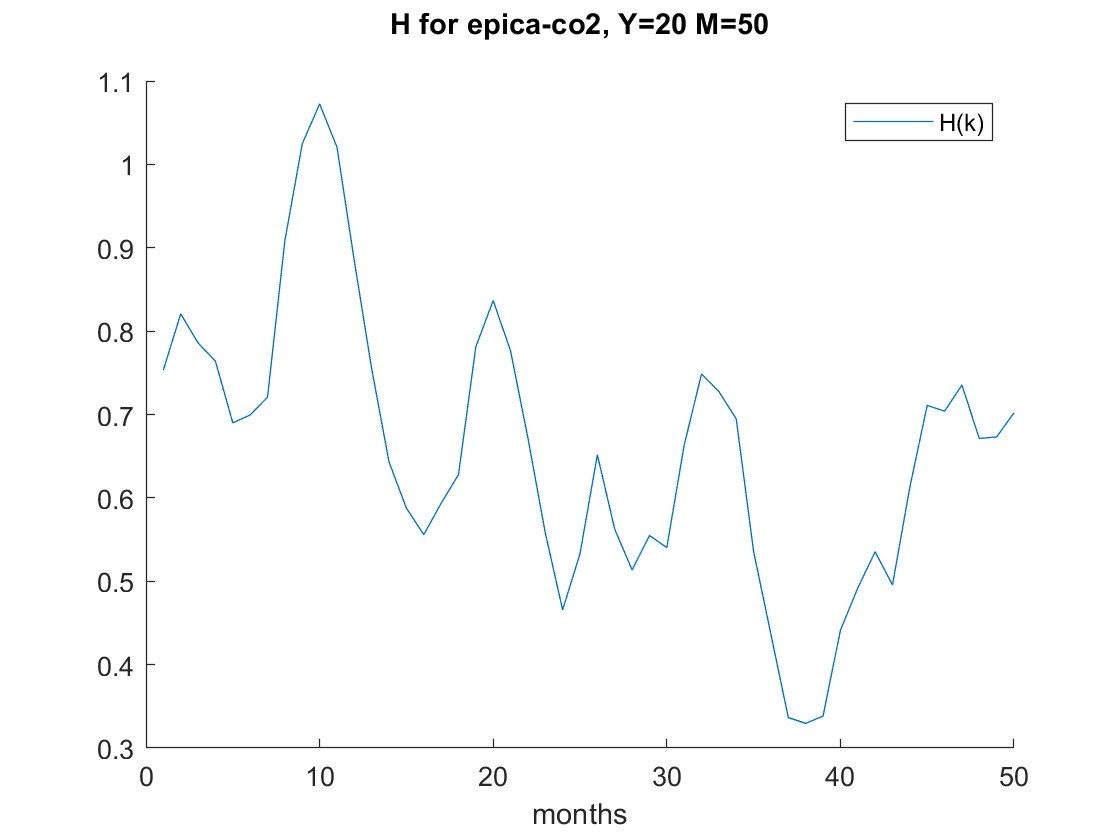

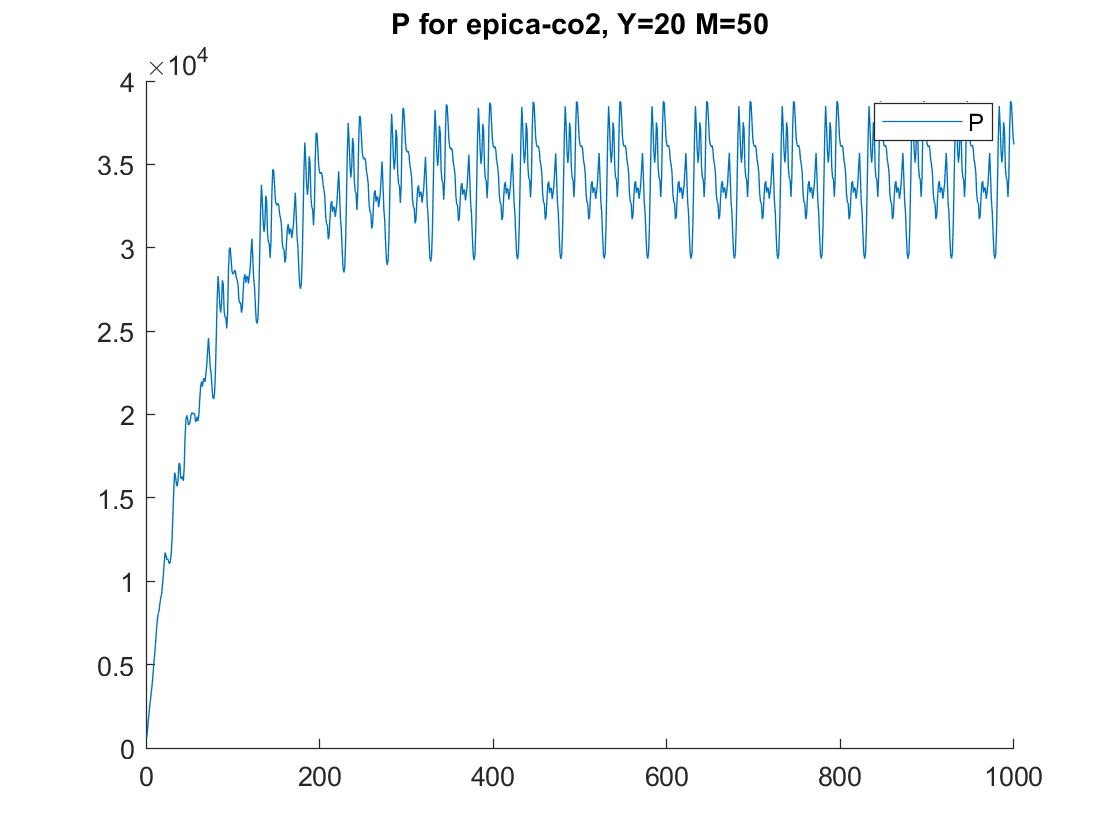

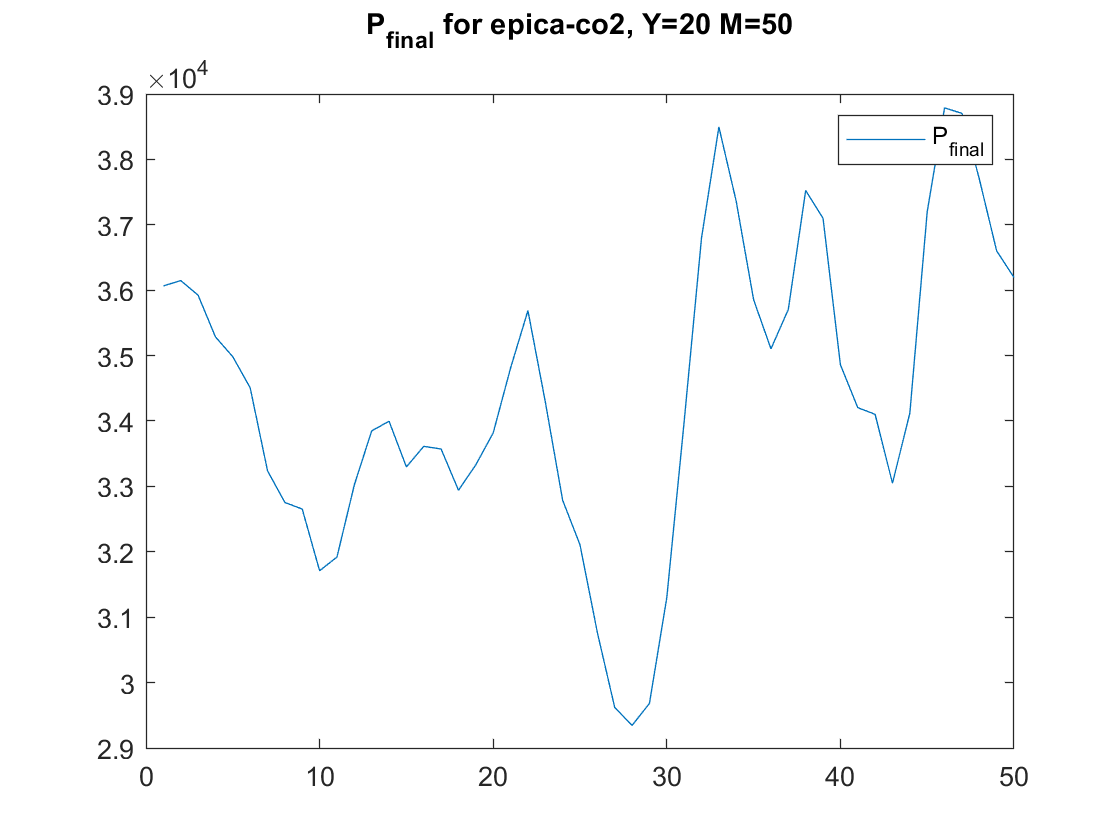

close all;
m = 5;
[a_final,N,f,P_final] = findanf_epica(epica_data,Y,M,m,1);

%%% trying my convergence idea thingy which didnt seem to work

% m = Y_est_round;
% 
% i = 1;
% close all;
% hold on;
% while i <= 15
%     
%     fprintf("iteration %d: m = %d\n",i,m);
%     
%     [a_final,~,~,~] = findanf_epica(epica_data,Y,M,m);
%     plot(a_final,'LineWidth',2);
%     int_a = sum(a_final) / M_length;
%     
%     T_a = 1 / abs(int_a);
%     num_M = T_a / M_length;
%     num_Y = num_M / M;
%     
%     if num_Y <= Y-2
%         m = round(num_Y);
%     else
%         m = Y - 2;
%     end
%     
%     i = i + 1;
% end
% legend("i=1","i=2","i=3","i=4","i=5","i=6","i=7","i=8","i=9","i=10");